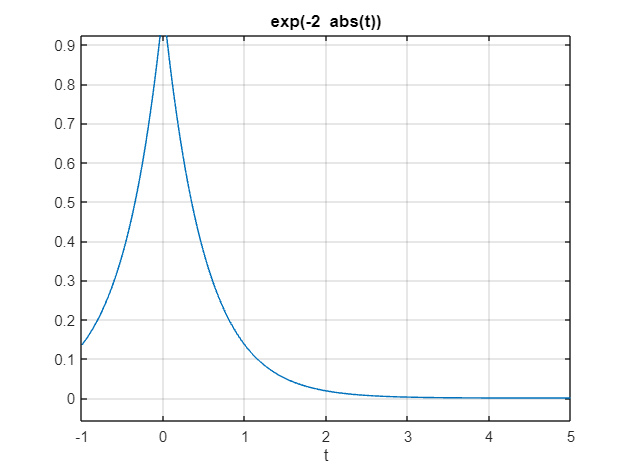

syms t

x = exp(-abs(2*t)) * cos(10*pi*t);
y = exp(-abs(2*t));

ezplot(y,[-1,5]); grid on;
hold on; 


k = 1; 
mag = zeros(size(-2:0.01:2)); 
phase = zeros(size(-2:0.01:2));
omega = -2:0.01:2; 

for f = -2:0.01:2
    Xw = int(x * exp(-1i*2*pi*f*t), t, -inf, inf);                                                                                                                                                              
    mag(k) = abs(Xw);
    phase(k) = angle(Xw);
    k = k + 1;
end


subplot(2,1,1);
plot(omega, mag, 'k');
title('X(\omega)'); xlabel('\omega'); grid on;

subplot(2,1,2);
plot(omega, phase, 'k');
title('Phase of X(\omega)'); xlabel('\omega'); 
grid on;